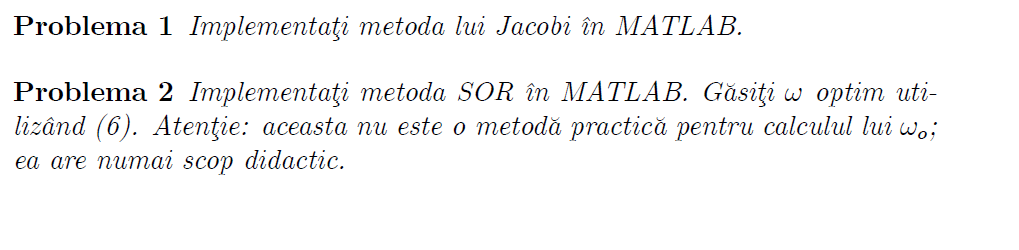

A=[5 -2 3 0;
    -3 9 1 -2;
    2 -1 -7 1;
    4 3 -5 7];

b=[-1 2 3 0.5]';

[x, iter] = jacobi(A, b)

x =     0.1787
    0.2303
   -0.4776
   -0.4705


iter = 8

[x, iter] = gauss_seidel(A, b)

x =     0.1787
    0.2303
   -0.4776
   -0.4706


iter = 6

[x, iter] = sor(A, b, 0.2)

x =     0.1784
    0.2311
   -0.4773
   -0.4688


iter = 39

 x = A \ b

x =     0.1787
    0.2303
   -0.4776
   -0.4705


clc
A=[5 -2 3 0;-3 9 1 -2;2 -1 -7 1; 4 3 -5 7];
b=[-1 2 3 0.5]';

eigvals = eig(A);
r = max(abs(eigvals));
omega = real(2 / (1 + sqrt(1 - r^2)));

tol = 1e-6;
iterMax = 1000;
%[x, iter] = sor(A, b, omega, tol, iterMax)

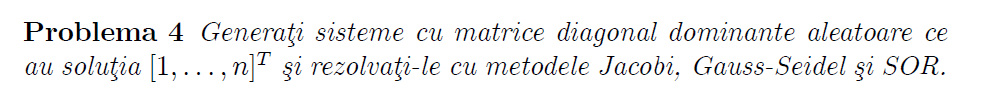

[A, b] = generate(10);
[x, iter] = jacobi(A, b)

x =     1.0038
    2.0042
    3.0041
    4.0044
    5.0041
    6.0039
    7.0040
    8.0041
    9.0042
   10.0041


iter = 61

[x, iter] = gauss_seidel(A, b)

x =     0.9997
    1.9998
    2.9999
    4.0001
    5.0002
    6.0002
    7.0001
    8.0001
    8.9999
   10.0000


iter = 6

[x, iter] = sor(A, b, 0.2)

x =     1.0356
    2.0460
    3.0139
    4.0275
    5.0115
    5.9580
    6.9765
    7.9886
    8.9824
    9.9781


iter = 26

function [A,b]=generate(n)
    x = [1:n]';
    A = rand(n);
    for i=1:n
        summ = 0;
        for j=1:n
            if i~=j
                summ = summ + A(i, j);
            end
        end
        A(i, i) = A(i, i) + summ;
    end
    b = A * x;
end